DATA 17.02

        u1                  u2            

B    1        0            0        0

C    0.5     0            0        0

D    0.5    0            0.5      0     

E    0        0            1        0

F    1        0            0.5    0

B

B, C

B, F

B, F, D

close all;
clear;
clc;

dataA = readtable('dataRecorded\01_03\03_03_TankA.csv');
%dataA = readtable('dataRecorded\01_03\01_03_sim12B.csv');
noise = 1E-6;

% x1A = [noise.* randn(20,1); dataA.y1; noise.* randn(100,1);];
% x2A  = [noise.* randn(20,1); dataA.y2; noise.* randn(100,1);];
% x3A  = [noise.* randn(20,1); dataA.y3; noise.* randn(100,1);];
x1A = dataA.y1;
x2A = dataA.y2;
x3A = dataA.y3;

%u1A = [zeros(20,1); dataA.u1; zeros(100,1);];
%u2A = dataA.u2;
u1A = dataA.u1

u1A = 	1.0e+-3 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



lengthA = length(x1A)

lengthA = 705


% 
% plot(u1A);
% hold on;
% plot(u2A);
% hold off;
% legend("u1",'u2');

DATA verarbeiten A

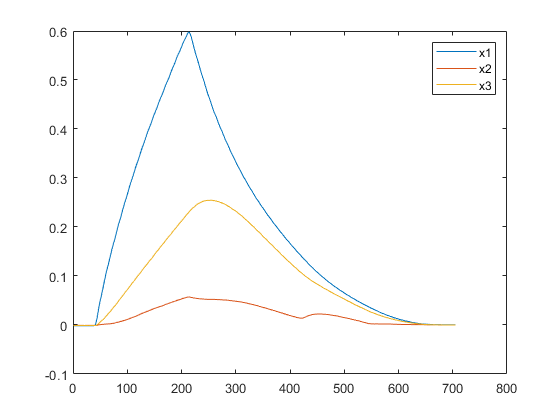

x1A = smoothdata(x1A,'gaussian',10);
x2A = smoothdata(x2A,'gaussian',10);
x3A = smoothdata(x3A,'gaussian',10);
dx1A = zeros(lengthA-1,1);
dx2A = dx1A;
dx3A = dx1A; 

for i = 2 : lengthA
%    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
%    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
%    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
    dx1A(i-1) = x1A(i)-x1A(i-1);
    dx2A(i-1) = x2A(i)-x2A(i-1);
    dx3A(i-1) = x3A(i)-x3A(i-1);
end
plot(x1A);
hold on;
plot(x2A);
plot(x3A);
hold off;
legend("x1",'x2','x3');

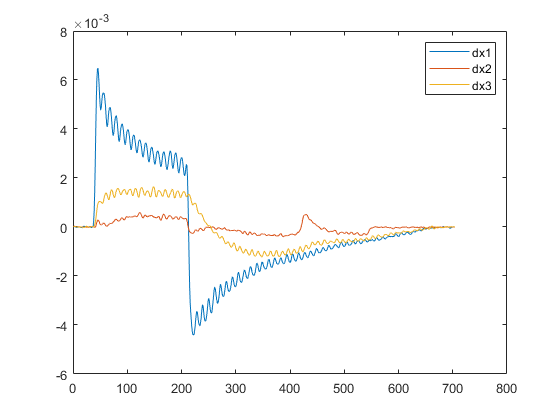


plot(dx1A);
hold on;
plot(dx2A);
plot(dx3A);
hold off;
legend("dx1",'dx2','dx3');

DATA B

dataB = readtable('dataRecorded\06_03\06_03_simB.csv');
noise = 5E-6;

% x1B = [noise.* randn(5,1); dataB.y1];
% x2B  = [noise.* randn(5,1); dataB.y2];
% x3B  = [noise.* randn(5,1); dataB.y3];

x1B = dataB.y1;
x2B  = dataB.y2;
x3B  = dataB.y3;


u1B = dataB.u1;
%u2B = dataB.u2;

lengthB = length(x1B)

lengthB = 633


%u1B(197:lengthB) = 0;

% plot(x1);
% hold on;
% plot(x2);
% plot(x3);
% hold off;
% legend("x1",'x2','x3');
% 
% plot(u1);
% hold on;
% plot(u2);
% hold off;
% legend("u1",'u2');

DATA verarbeiten B

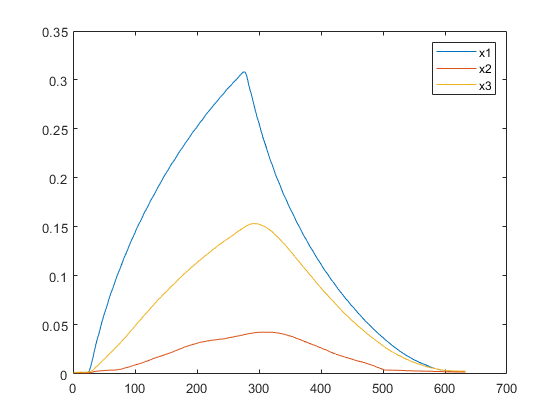

x1B = smoothdata(x1B,'gaussian',10);
x2B = smoothdata(x2B,'gaussian',10);
x3B = smoothdata(x3B,'gaussian',10);
dx1B = zeros(lengthB-1,1);
dx2B = dx1B;
dx3B = dx1B;

for i = 2 : lengthB
%    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
%    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
%    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
    dx1B(i-1) = x1B(i)-x1B(i-1);
    dx2B(i-1) = x2B(i)-x2B(i-1);
    dx3B(i-1) = x3B(i)-x3B(i-1);
end
plot(x1B);
hold on;
plot(x2B);
plot(x3B);
hold off;
legend("x1",'x2','x3');

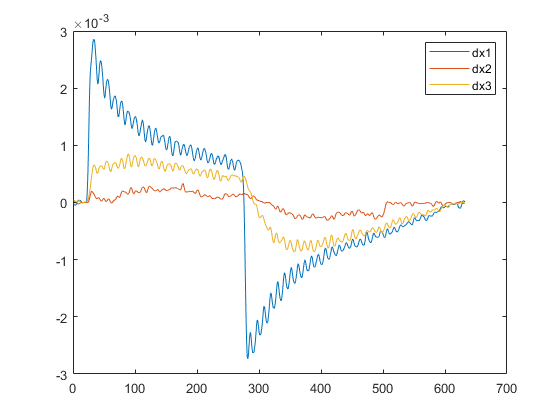


plot(dx1B);
hold on;
plot(dx2B);
plot(dx3B);
hold off;
legend("dx1",'dx2','dx3');

DATA C

dataC = readtable('dataRecorded\01_03\01_03_sim12B.csv');
noise = 1E-6;

x1C = [noise.* randn(5,1); dataC.y1];
x2C  = [noise.* randn(5,1); dataC.y2];
x3C  = [noise.* randn(5,1); dataC.y3];

u1C = dataC.u1;
u2C = dataC.u2;

lengthC = length(x1C)

lengthC = 813


%u1C(197:lengthC) = 0;

% plot(x1);
% hold on;
% plot(x2);
% plot(x3);
% hold off;
% legend("x1",'x2','x3');
% 
% plot(u1);
% hold on;
% plot(u2);
% hold off;
% legend("u1",'u2');

DATA verarbeiten C

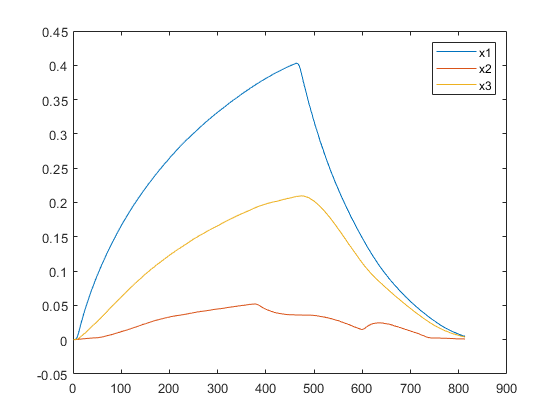

x1C = smoothdata(x1C,'gaussian',15);
x2C = smoothdata(x2C,'gaussian',15);
x3C = smoothdata(x3C,'gaussian',15);
dx1C = zeros(lengthC-1,1);
dx2C = dx1C;
dx3C = dx1C;

for i = 2 : lengthC
%    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
%    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
%    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
    dx1C(i-1) = x1C(i)-x1C(i-1);
    dx2C(i-1) = x2C(i)-x2C(i-1);
    dx3C(i-1) = x3C(i)-x3C(i-1);
end
plot(x1C);
hold on;
plot(x2C);
plot(x3C);
hold off;
legend("x1",'x2','x3');

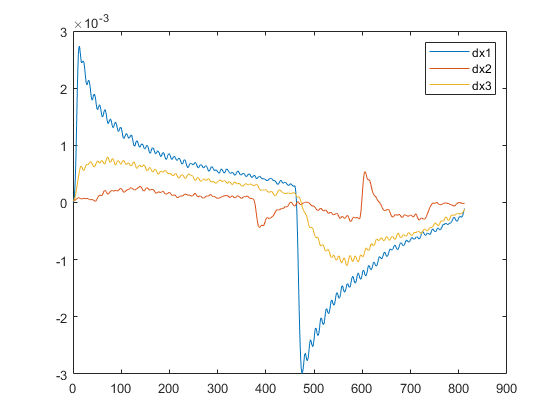


plot(dx1C);
hold on;
plot(dx2C);
plot(dx3C);
hold off;
legend("dx1",'dx2','dx3');

All DATA together

targetLength = 120; %floor(lengthA / 6); %150;
divisions = 1;%3
divLength = targetLength / divisions;
extraLength = 0;

x1 = zeros(targetLength,1); x2 = x1; x3 = x1; 
u1 = x1; u2 = x1;
dx1 = x1; dx2 = x1; dx3 = x1;

div1: A from 0 to max

length1 = lengthA;%162
div1 = floor(length1/divLength);
for i = 1 : divLength %+ 1
    pos = (i-1)*div1 + 1;
    count  = i;
    x1(count) = x1A(pos);
    x2(count) = x2A(pos);
    x3(count) = x3A(pos);
    
    dx1(count) = dx1A(pos);
    dx2(count) = dx2A(pos);
    dx3(count) = dx3A(pos);
   
        u1(count) = u1A(pos) ;
    %u2(count) = u2A(pos);
end


div2: B from 0 to max

% length2 = lengthB;
% div2 = floor(length2/divLength);
% for i = 1 : divLength
%     pos = (i-1)*div2 + 1;
%     count  = i + divLength;
%     x1(count) = x1B(pos);
%     x2(count) = x2B(pos);
%     x3(count) = x3B(pos);
%     
%     dx1(count) = dx1B(pos);
%     dx2(count) = dx2B(pos);
%     dx3(count) = dx3B(pos);
%     
%     u1(count) = u1B(pos);
%     %u2(count) = u2B(pos);
% end

div3: C from max to zero

% %length1=162;
% length3Start = 1;
% length3End  = lengthC;
% 
% div3 = floor((length3End -length3Start)/divLength);
% for i = 1 : divLength
%     pos = (i-1)*div3 + length3Start;
%     count  = i + 2*divLength; % * 2
%     x1(count) = x1C(pos);
%     x2(count) = x2C(pos);
%     x3(count) = x3C(pos);
%     
%     dx1(count) = dx1C(pos);
%     dx2(count) = dx2C(pos);
%     dx3(count) = dx3C(pos);
%     
%     u1(count) = u1C(pos);
%     u2(count) = u2C(pos);
% end

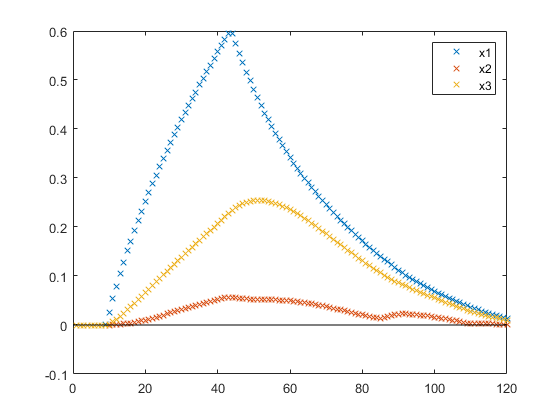

plot(x1,"x");
hold on;
plot(x2,"x");
plot(x3,"x");
plot([0;targetLength],[0;0],"black")
hold off;
legend("x1",'x2','x3');

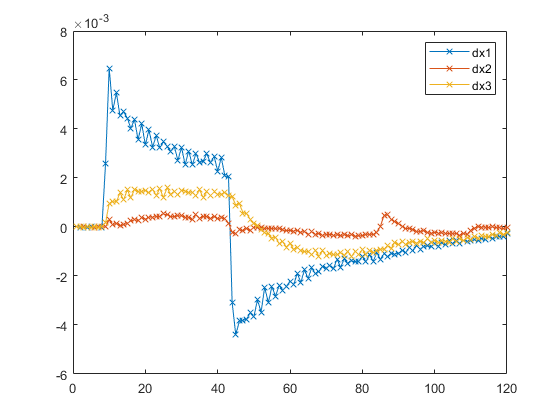


plot(dx1,"x-");
hold on;
plot(dx2,"x-");
plot(dx3,"-x");
hold off;
legend("dx1",'dx2','dx3');

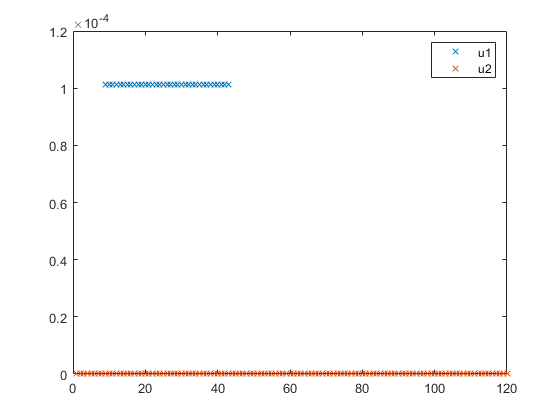



plot(u1,"x");
hold on;
plot(u2,"x");
hold off;
legend("u1",'u2');

% 
testData = table(x1,x2,x3,dx1,dx2,dx3,u1);
save("dataOut/testData31.mat","testData");
writetable(testData,"dataOut/testData31.csv",'Delimiter',';');